Numerical Derivative

- Slope of lines on a graph

- How y is changing as x changes (with respect to x)

- dy/dx = deltay/deltax

- diff takes in a vector of numbers and finds difference between adjacent

- numbers - gives back one fewer elements

figure
hold on
grid on


Linear

x = 1:4

x =      1     2     3     4


y = [1, 3, 2, 4];
diff(x)

ans =      1     1     1


diff(y)

ans =      2    -1     2


first = diff(y) ./ diff(x)

first =      2    -1     2


plot(x,y,'r') %Plot original data
plot(x(1:end-1),diff(y),'g') %Plot Derivative


Using sin

x = 0:360;
y = sind(x);
diff(x)

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


diff(y)

ans =     0.0175    0.0174    0.0174    0.0174    0.0174    0.0174    0.0173    0.0173    0.0173    0.0172    0.0172    0.0171    0.0170    0.0170    0.0169    0.0168    0.0167    0.0166    0.0166    0.0165    0.0163    0.0162    0.0161    0.0160    0.0159    0.0158    0.0156    0.0155    0.0153    0.0152    0.0150    0.0149    0.0147    0.0146    0.0144    0.0142    0.0140    0.0138    0.0137    0.0135    0.0133    0.0131    0.0129    0.0127    0.0124    0.0122    0.0120    0.0118    0.0116    0.0113


first = diff(y) ./ diff(x)

first =     0.0175    0.0174    0.0174    0.0174    0.0174    0.0174    0.0173    0.0173    0.0173    0.0172    0.0172    0.0171    0.0170    0.0170    0.0169    0.0168    0.0167    0.0166    0.0166    0.0165    0.0163    0.0162    0.0161    0.0160    0.0159    0.0158    0.0156    0.0155    0.0153    0.0152    0.0150    0.0149    0.0147    0.0146    0.0144    0.0142    0.0140    0.0138    0.0137    0.0135    0.0133    0.0131    0.0129    0.0127    0.0124    0.0122    0.0120    0.0118    0.0116    0.0113


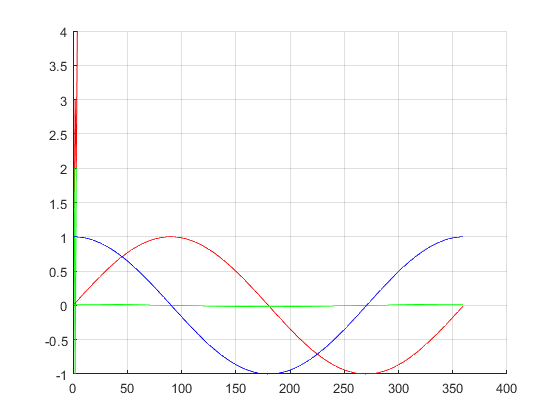

scale= 1/max(diff(y));
plot(x,y,'r') %Plot original data
plot(x(2:end),diff(y),'g') %Plot Derivative
plot(x(2:end),scale*diff(y),'b') %Plot scaled Derivative

Analytical Derivative (Power Rule)

- 2*x^2 + 4*x + 5 ---> 4*x + 4

- Multiply [2 4 5] by [2 1 0]  ---> [4 4 0]

figure
hold on
grid on

coeffs = [2 4 5]

coeffs =      2     4     5


pow = length(coeffs)-1 : -1 : 0

pow =      2     1     0


newcoeffs = coeffs .* pow

newcoeffs =      4     4     0


newcoeffs(end) = []

newcoeffs =      4     4



x = 0:.1:10;

y = polyval(coeffs, x)

y =     5.0000    5.4200    5.8800    6.3800    6.9200    7.5000    8.1200    8.7800    9.4800   10.2200   11.0000   11.8200   12.6800   13.5800   14.5200   15.5000   16.5200   17.5800   18.6800   19.8200   21.0000   22.2200   23.4800   24.7800   26.1200   27.5000   28.9200   30.3800   31.8800   33.4200   35.0000   36.6200   38.2800   39.9800   41.7200   43.5000   45.3200   47.1800   49.0800   51.0200   53.0000   55.0200   57.0800   59.1800   61.3200   63.5000   65.7200   67.9800   70.2800   72.6200


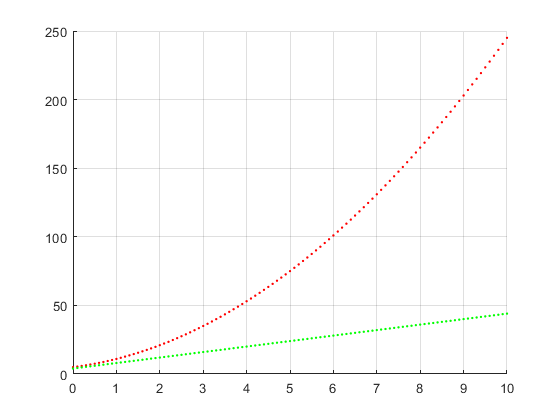

plot(x,y,'r.', 'markersize', 5)

newy = polyval(newcoeffs, x);
plot(x,newy,'g.', 'markersize', 5)
axis([0 10 0 250])